# Ejercicio 5 (2,5 puntos). Error de posición y velocidad en estado estacionario.

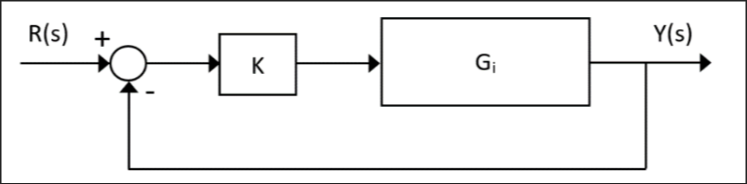

a) Calcula el error de posición (absoluto y relativo) del sistema de control en lazo cerrado de la figura, frente al escalón de amplitud igual a 2, donde Gi=G1 (del ejercicio 4) y K=1. Razona qué significan los valores de error absoluto y relativo obtenidos, poniendo un ejemplo práctico.

K=1

K = 1

Gi = zpk([],[-5+4j, -5-4j,-2],200)

Gi =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Gik = series(K,Gi)

Gik =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Glc = feedback(Gik,1)%feedback unitario negativo

Glc =
 
                200
  --------------------------------
  (s+8.714) (s^2 + 3.286s + 32.36)
 
Continuous-time zero/pole/gain model.
Model Properties


Amplitude = 2

Amplitude = 2

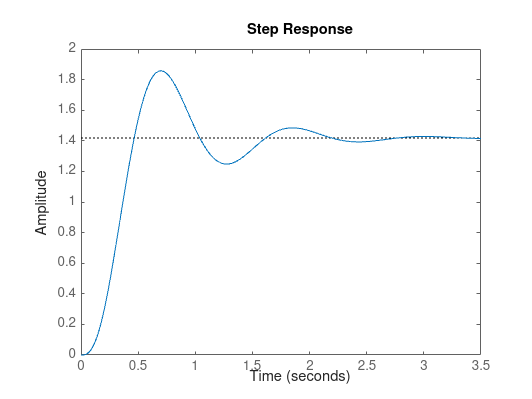

step(Glc * Amplitude)

[y,t]=step(Glc*Amplitude);
ess_pos_abosoluto=Amplitude-y(end)

ess_pos_abosoluto = 0.5747

ess_pos_relativo=(Amplitude-y(end))*100/Amplitude  

ess_pos_relativo = 28.7368

b) ¿Puedes sustituir K por una función de transferencia C(s) de tal manera que el error de posición en estado estacionario desaparezca completamente? Justifica tu respuesta y compruébala utilizando MATLAB.

Para calcular el error estacionario (ess) de posición debemos resolver el siguiente límite

En nuestro caso R(s) es 200/s ya que es una entrada de rampa, de tal forma que para que el error desasparezca, el limite de s-> 0, de G(s) . H(s) tiene que dar infinito (En nuestro caso sería Gi x K)

%Para ello, convertimos H(s) de 1 a 1/s
%De esta forma el límite dará infinito y por ende el error será nulo
syms s;
K=zpk([],0,1)

K =
 
  1
  -
  s
 
Continuous-time zero/pole/gain model.
Model Properties


Gi = zpk([],[-5+4j, -5-4j,-2],200)

Gi =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Gik = series(K,Gi)

Gik =
 
            200
  ------------------------
  s (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


tf(Gik)

ans =
 
              200
  ----------------------------
  s^4 + 12 s^3 + 61 s^2 + 82 s
 
Continuous-time transfer function.
Model Properties


KGi= 200/(s^4+12*s^3+61*s^2+82*s)

$$KGi = \frac{200}{s^{4}+12\,s^{3}+61\,s^{2}+82\,s}$$

exp = 2/(1+KGi)

$$exp = \frac{2}{\frac{200}{s^{4}+12\,s^{3}+61\,s^{2}+82\,s}+1}$$

lim = limit(exp,s,0)

$$lim = 0$$

De esta forma el límite da cero y por ende, el valor teórico de error estacionario también será 0.

Teniendo en cuenta que es imposible tener un K infinito, ya que el si analizamos el límite especificamente en Gi. K, dará una indeterminación y tampoco hace sentido conseguir una ganancia infinita.

Es por esto que matlab no mostrará un error nulo cuando lo grafiquemos, pero dara un valor cercano


K=zpk([], 0,1)%1/s

K =
 
  1
  -
  s
 
Continuous-time zero/pole/gain model.
Model Properties


Gi = zpk([],[-5+4j, -5-4j,-2],200)

Gi =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Gik = series(K,Gi)

Gik =
 
            200
  ------------------------
  s (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Glc = feedback(Gik,1)%feedback unitario negativo

Glc =
 
                       200
  ----------------------------------------------
  (s^2 + 0.7333s + 4.113) (s^2 + 11.27s + 48.62)
 
Continuous-time zero/pole/gain model.
Model Properties


Amplitude = 2

Amplitude = 2

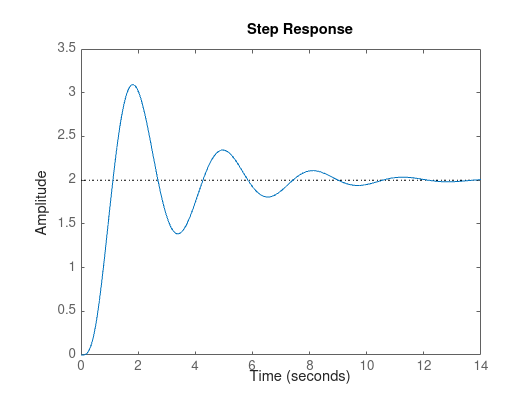

figure; step(Glc * Amplitude)

[y,t]=step(Glc*Amplitude);
ess_pos_abosoluto=Amplitude-y(end)

ess_pos_abosoluto = -0.0046

ess_pos_relativo=(Amplitude-y(end))*100/Amplitude  

ess_pos_relativo = -0.2318

c) Calcula el error de velocidad (absoluto y relativo) del sistema de control dado por G2 (del ejercicio 4) frente a la entrada rampa de pendiente igual a 3, con K=1. Razona qué significan los valores de error absoluto y relativo obtenidos.

Primero definimos las funciones

K=1

K = 1

Gi = zpk([],[-5+4j, -5-4j,-5],500)

Gi =
 
           500
  ----------------------
  (s+5) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Gik = series(K,Gi)

Gik =
 
           500
  ----------------------
  (s+5) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


Glc = feedback(Gik,1)%feedback unitario negativo

Glc =
 
                500
  --------------------------------
  (s+12.27) (s^2 + 2.733s + 57.47)
 
Continuous-time zero/pole/gain model.
Model Properties


Como matlab no tiene una función de rampa, tenemos que usar linspace y simular la rampa nosotros mismos

t=linspace(0,10,100)

t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


rampa = 3*t

rampa =          0    0.3030    0.6061    0.9091    1.2121    1.5152    1.8182    2.1212    2.4242    2.7273    3.0303    3.3333    3.6364    3.9394    4.2424    4.5455    4.8485    5.1515    5.4545    5.7576    6.0606    6.3636    6.6667    6.9697    7.2727    7.5758    7.8788    8.1818    8.4848    8.7879    9.0909    9.3939    9.6970   10.0000   10.3030   10.6061   10.9091   11.2121   11.5152   11.8182   12.1212   12.4242   12.7273   13.0303   13.3333   13.6364   13.9394   14.2424   14.5455   14.8485


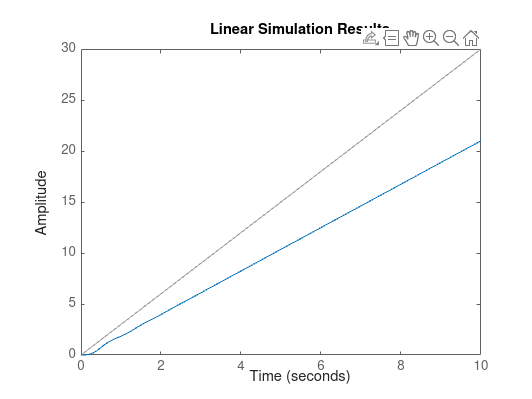

figure; lsim(Glc,rampa,t)

[y,t]=lsim(Glc,rampa,t);
ess_vel_absoluto=rampa(end)-y(end)

ess_vel_absoluto = 8.9980

ess_vel_relativo=(rampa(end)-y(end))*100/rampa(end) %Percentage error

ess_vel_relativo = 29.9935

kv = 0.1111

El valor del error absoluto significa que la respuesta o salida del sistema no alcanza a la entrada

También podemos ver que mientras mas grande sea el rango de tiempo que usemos, mayor será el error, es decir, para t-> inf, ess_vel = inf. Y esto sucede porque estamos usando una entrada rampa en un sistema de tipo 0, sin integradores que permitan regular la entrada. 

Ahora bien, si analizamos específicamente los valores, para el instante de t=10 (en el que se hacen los calculos), la entrada tiene valor de 30, mientras que la salida tiene valor de 30 - 8.99 ≈ 21. Lo cual representa casi una diferencia o desfase del 30%, que es justo lo que indica el error estacionario relativo.

Si quisieramos verlo en un ejemplo de la vida real, si tenemos un carro de juguete al que una velocidad de entrada de 9 m/s, la velocidad real del carrito será 21 m/s, demostrando que el sistema se va atrasando.

Para maneja una entrada de tipo rampa, tendríamos que añadir un bloque al feedback, de tal forma que puede ir corrigiendo el error mientras el tiempo crece.